# Antenna Analysis

clear all
set(0,'DefaultFigureWindowStyle','docked')


## Frquency Bandwidths

Band=   ["L","S","C","X","K_u","K","K_a","V"];
f   =   [1,2,4,8,12,18,27,40];%GHz

## Antennas

Range

n=50;
l=linspace(1/f(1),1/f(end),n);

D=.1;
h=226.3e-3;
A=D*h;
L=D;

dipole=ones([1,n])*1.64;
planer=10*log10(A./l.^2) + 8;
turnstile=ones([1,n])*0.6;
horn=20*log10(D./l) + 7;
bicone=5*log10(D./l) + 3.5;
helix=10*log10((D^2)*L./(l.^3)) + 20.2;
parabola=20*log10(1./l) + 20*log10(D) + 17.8;
yagi=ones([1,n])*12;

planer(planer<0)=0;
horn(horn<0)=0;
bicone(bicone<0)=0;
helix(helix<0)=0;
parabola(parabola<0)=0;

## Plots

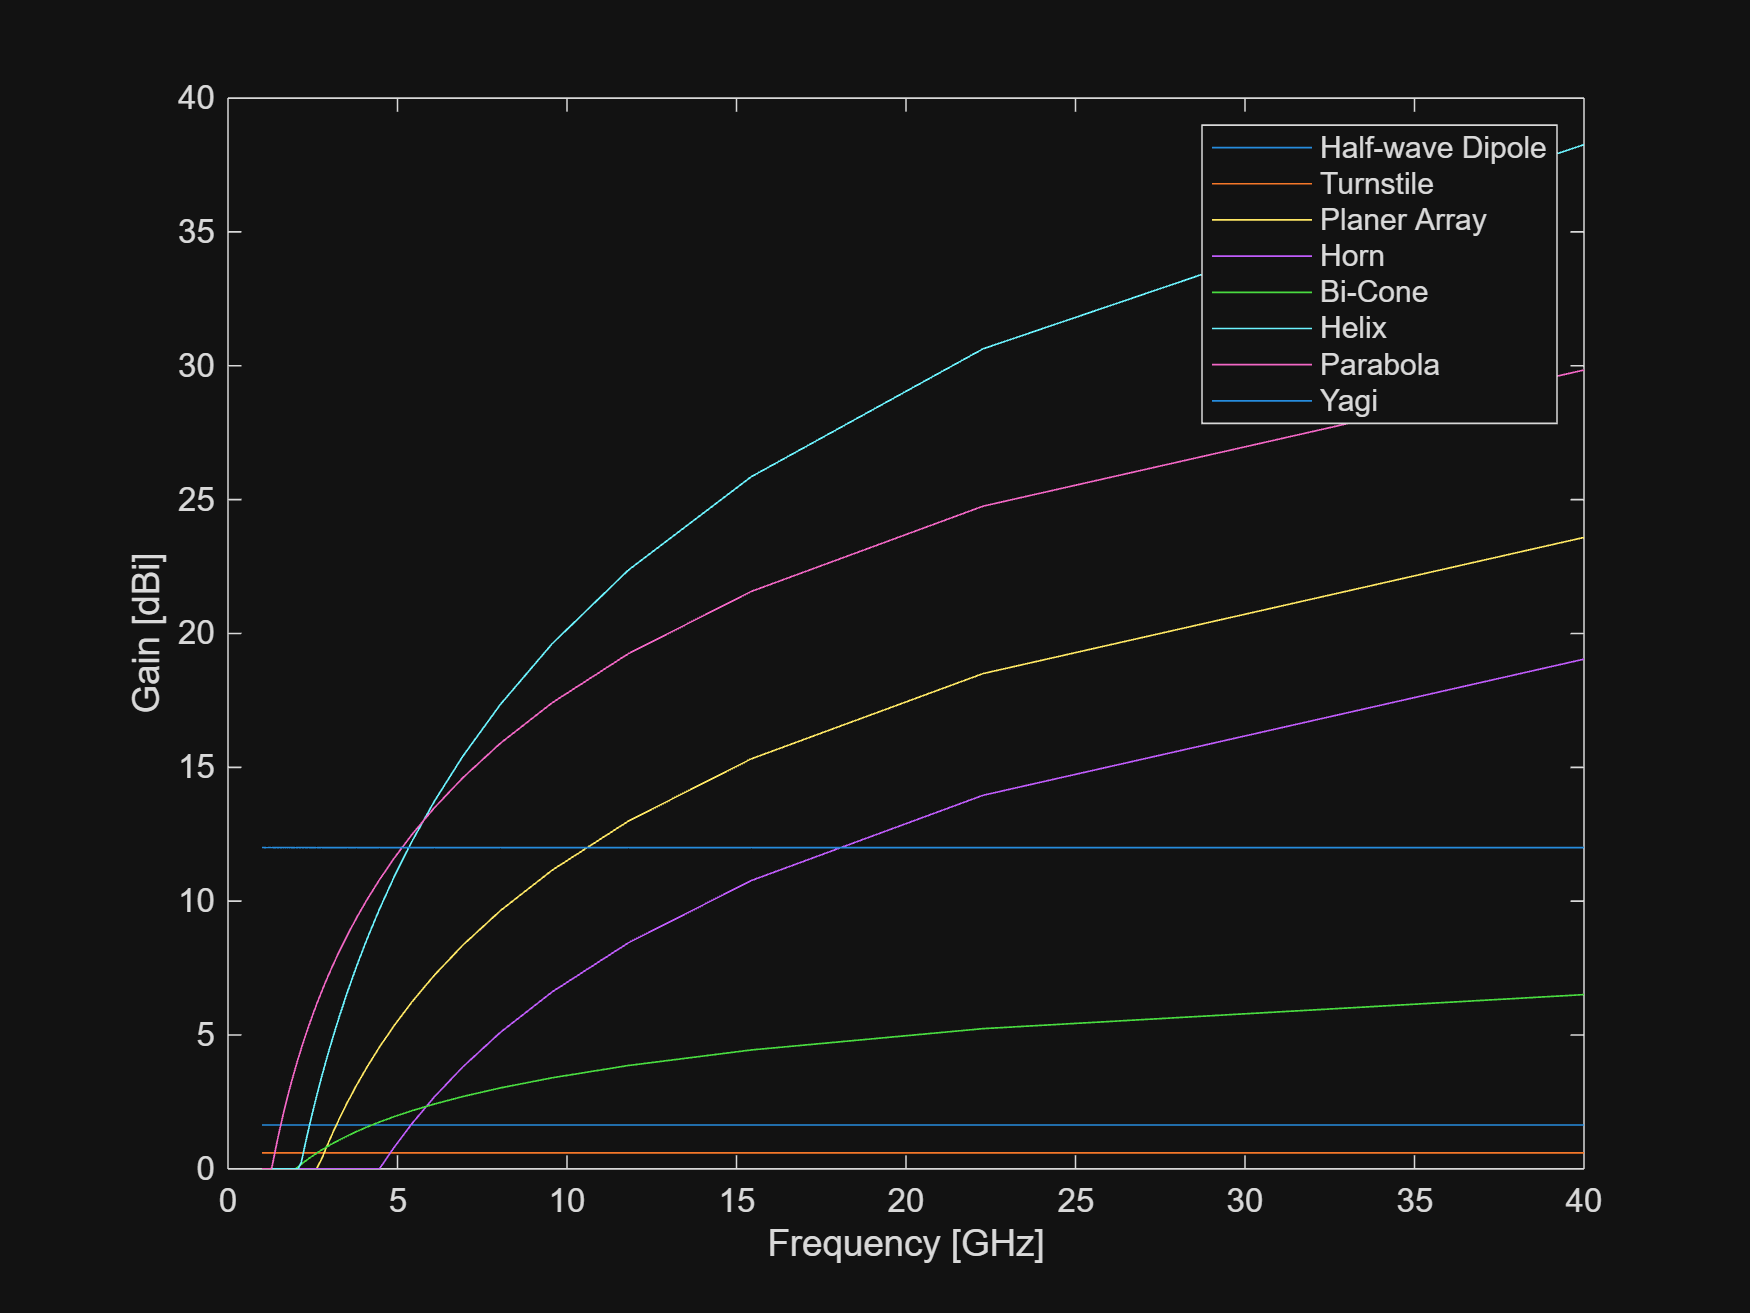

close all
freq=1./l;

figure(1)
plot(freq,dipole,DisplayName="Half-wave Dipole")
hold on
plot(freq,turnstile,DisplayName="Turnstile")
plot(freq,planer,DisplayName="Planer Array")
plot(freq,horn,DisplayName="Horn")
plot(freq,bicone,DisplayName="Bi-Cone")
plot(freq,helix,DisplayName="Helix")
plot(freq,parabola,DisplayName="Parabola")
plot(freq,yagi,DisplayName="Yagi")
ylabel("Gain [dBi]")
xlabel("Frequency [GHz]")
legend()
%ColorCorrection(gcf)
% for i=f(:,1:end-1)
%     area(x(x>f(i)&x<f(i+1)),z(x>f(i)&x<f(i+1)))%,"FaceColor","r","FaceAlpha",0.5)
%     area(x(x>f(i)&x<f(i+1)),-z(x>f(i)&x<f(i+1)))%,"FaceColor","r","FaceAlpha",0.5)
% end
hold off


range=@(x) Range(x,freq);
figure(2)
plot(freq,range(dipole),DisplayName="Half-wave Dipole")
hold on

plot(freq,range(turnstile),DisplayName="Turnstile")
plot(freq,range(horn),DisplayName="Horn")
plot(freq,range(bicone),DisplayName="Bi-Cone")
plot(freq,range(helix),DisplayName="Helix")
plot(freq,range(parabola),DisplayName="Parabola")
plot(freq,range(yagi),DisplayName="Yagi")
ylabel("Distance [km]")
xlabel("Frequency [GHz]")
legend()
%ColorCorrection(gcf)
hold off

## Range

function d = Range(gain,f)
    d = 10*(gain - 32.44 - f*1000);
end
    